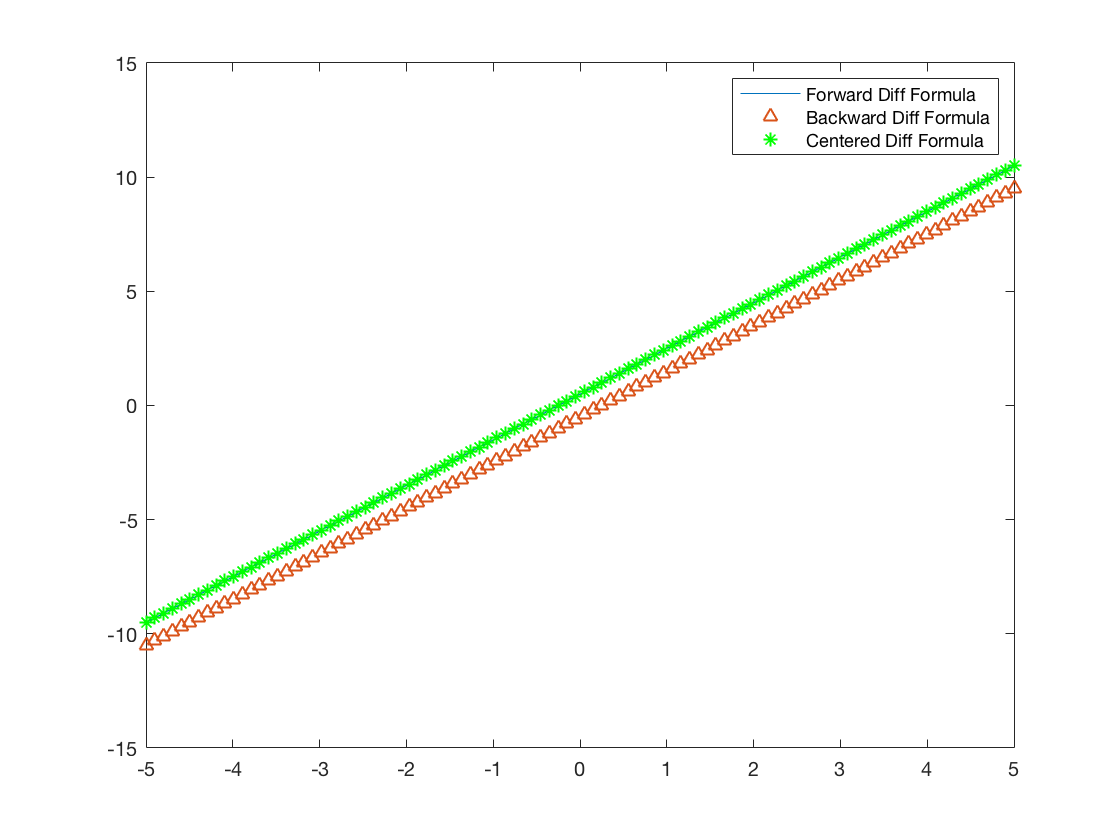

X = linspace(-5,5,100);
h = 0.5;

% f = @(x) x; %All three formulas look similar.
f = @(x) x.^2; %Center and Forward overshoot while backward undershoots the values.
% f = @(x) x.^3;
% - Center and Forward undershoots while Backward overshoots on the left side of the parabola.
% - Center and Forward overshoots while Backward undershoots on the right side of the parabola. 
% f = @(x) sin(x);
% - Center and Forward undershoots while Backward overshoots.

forward = @(x,h) (f(x+h)-f(x))/h;
backward = @(x,h) (f(x)-f(x-h))/h;
centered = @(x,h) (f(x+h)-f(x-h))/2*h;

plot(X,forward(X,h),'-',X,backward(X,h),'^',X,forward(X,h),'g*');
legend('Forward Diff Formula','Backward Diff Formula', 'Centered Diff Formula');